Einlesen eines Bildes mit imread

cam = imread("./cameraman.png");

Bild verrauschen

A = cam + randi([0, 255], size(A), "uint8");

Oberes linkes Viertel auswählen

cam_quarter_tl = A(1:256, 1:end/2);

Unteres Rechtes Viertel auswählen

cam_quarter_br = A(257:end, 257:end);

Bild anzeigen

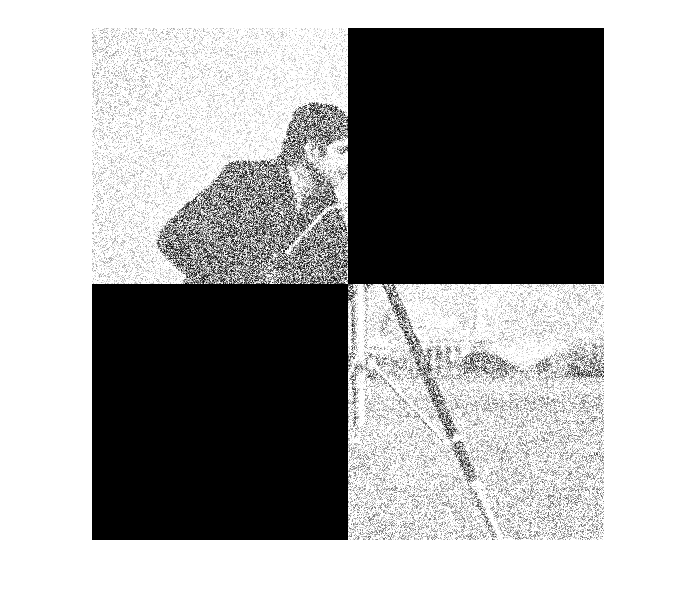

imshow([cam_quarter_tl, 0 * cam_quarter_br; 0 * cam_quarter_br, cam_quarter_br])

Bild auf die hälfte verkleinern (in jeder Dimension). Hier: wähle jeden zweiten Pixel in jeder Dimension

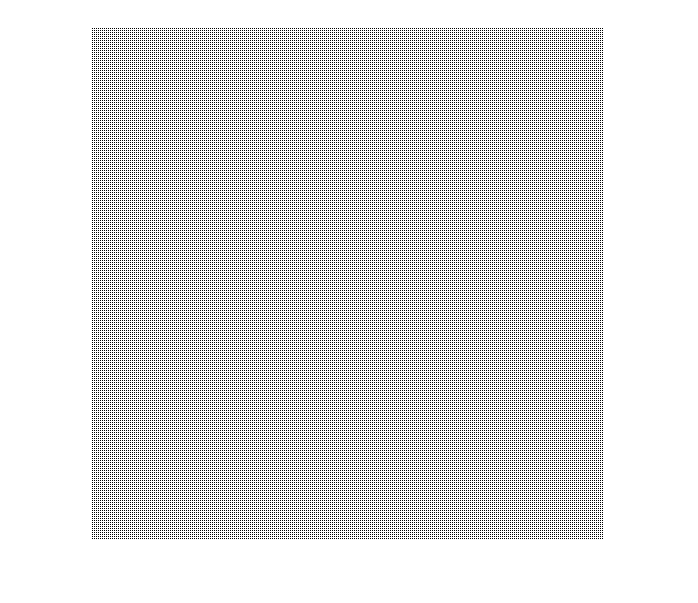

Z = zeros(512, 512);
A = ones(512, 512);
A(1:2:end, 1:2:end) = Z(1:2:end, 1:2:end);
imshow(A)

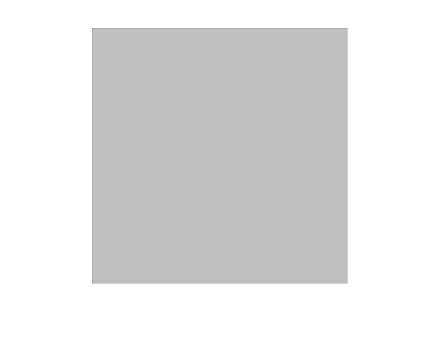

imshow(imresize(A, 0.5))

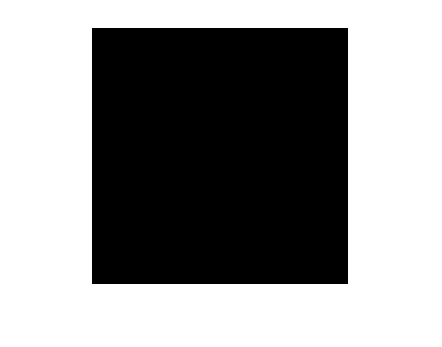

imshow(A(1:2:end, 1:2:end))

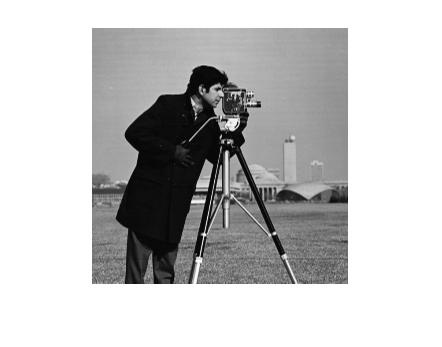

imshow(cam(1:2:end, 1:2:end))

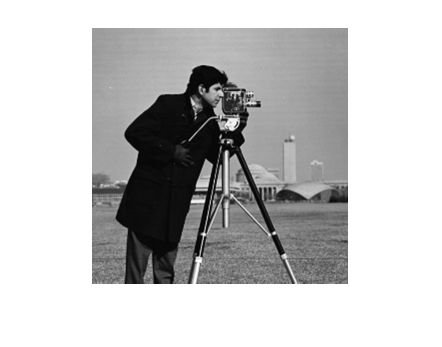

imshow(imresize(cam, 0.5))

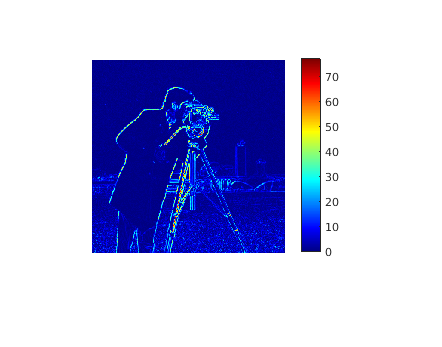

diff = double(imresize(cam, 0.5)) - double(cam(1:2:end, 1:2:end));
% imshow(diff) % normalisiert auf [0,1]
imshow(abs(diff), []) % normalisiert nicht
colormap jet
colorbar

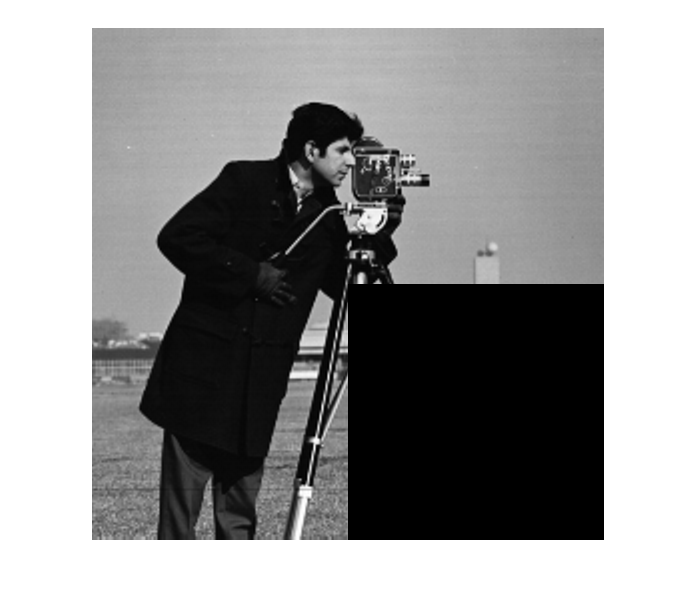

cam_black = cam;
cam_black(end/2+1:end, end/2+1:end) = 0; % zeros(size(cam)/2)
imshow(cam_black)

Setze 100. Zeile auf Weiß

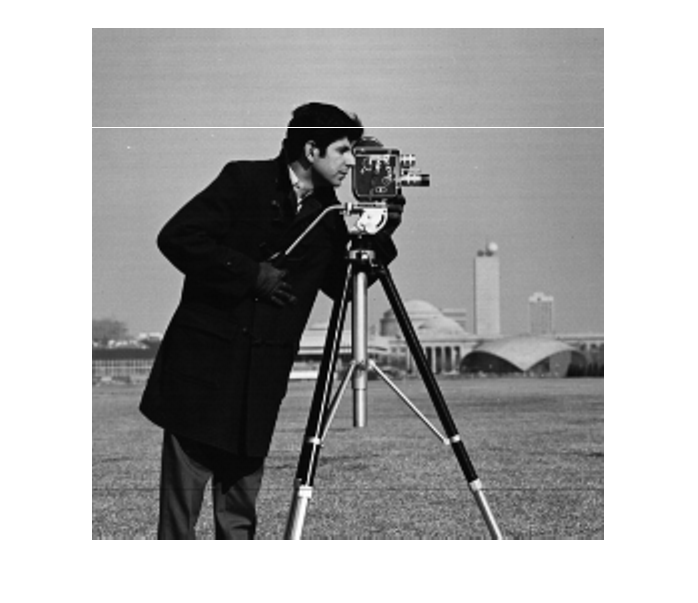

cam_white = cam;
cam_white(100, :) = 255;
imshow(cam_white)

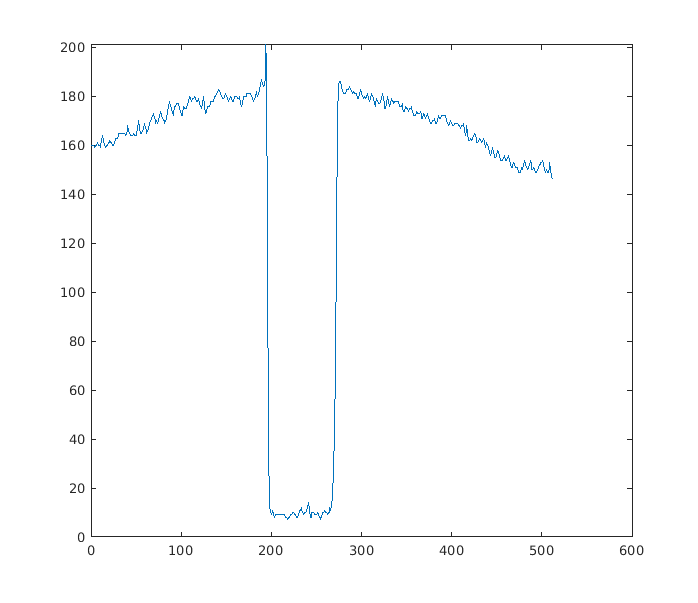

plot(cam(100,:))

Spiegle das Bild horizontal

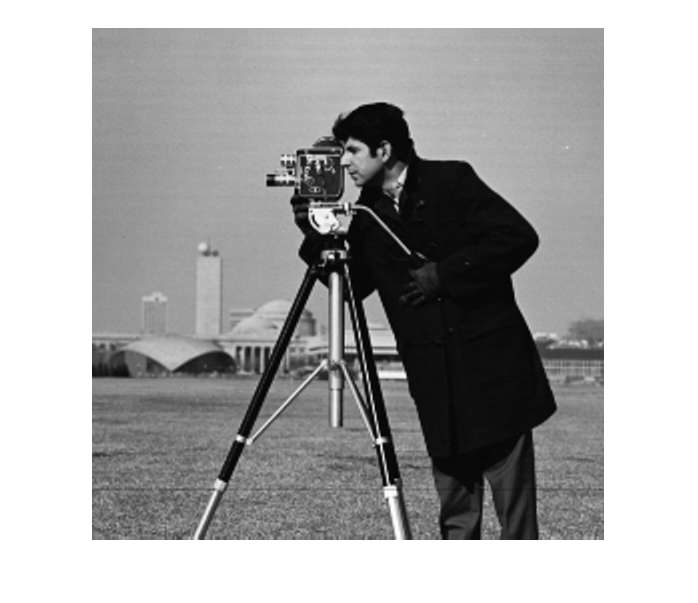

imshow(cam(:, end:-1:1))

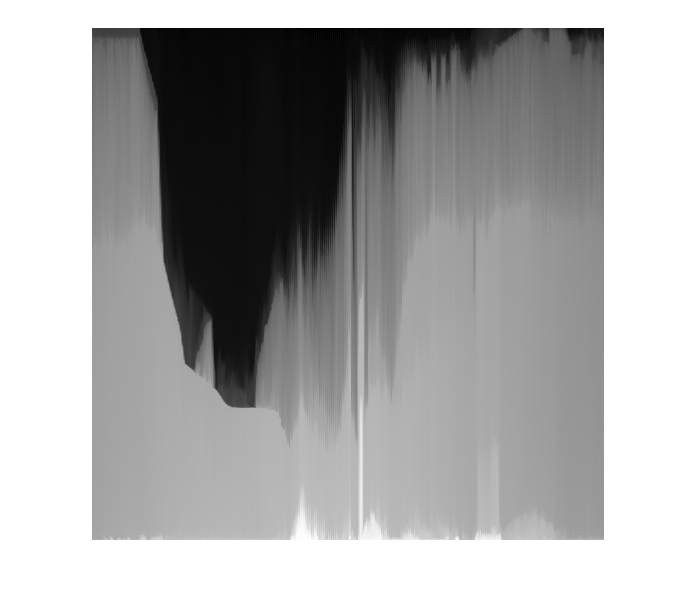

imshow(sort(cam))